# Image compression using PCA

SLectured by Sujin Jang in ECE662 2014 Spring, Purdue University Refer to "Principal Component Analysis", lecture note on May 2009, M. Richardson ([http://people.maths.ox.ac.uk/richardsonm/SignalProcPCA.pdf](http://people.maths.ox.ac.uk/richardsonm/SignalProcPCA.pdf)) for detailed description and original Matlab code.

## upraveno 22.11.2023 - MP

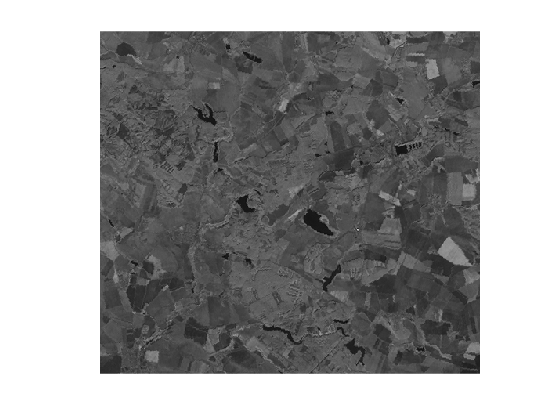

clear all; close all; clc;
[fly,map] = imread('Lp4.bmp'); % load image into MATLAB
fly=double(fly); % convert to double precision
figure;
image(fly),colormap(map); % display image
axis off, axis equal

[m n]=size(fly);
mn = mean(fly,2); % compute row mean
X = fly - repmat(mn,1,n); % subtract row mean to obtain X
Z=1/sqrt(n-1)*X'; % create matrix, Z
covZ=Z'*Z; % covariance matrix of Z

## Singular value decomposition

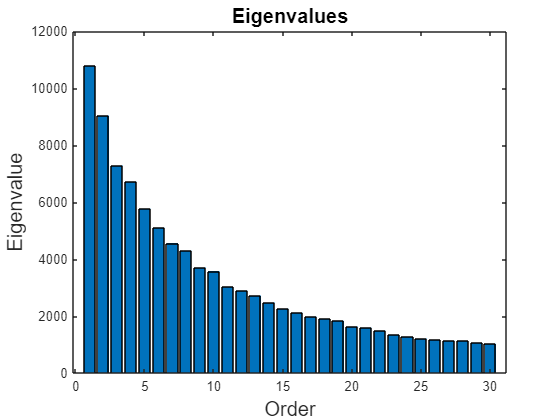

[U,S,V] = svd(covZ);
variances=sqrt(diag(S).*diag(S)); % compute variances
figure;
bar(variances(1:30)) % scree plot of variances
title('Eigenvalues', 'FontSize',15);
xlabel('Order','FontSize',15); ylabel('Eigenvalue', 'FontSize',15);

## Extract first 20 principal components

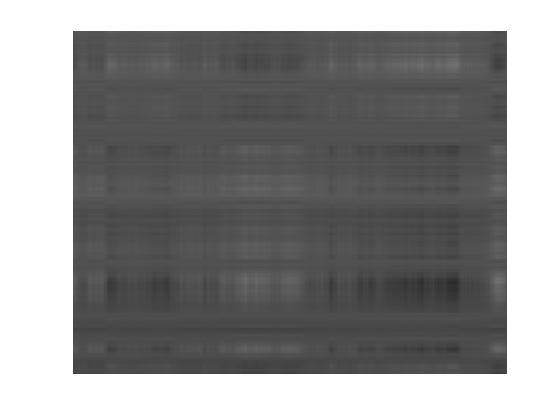

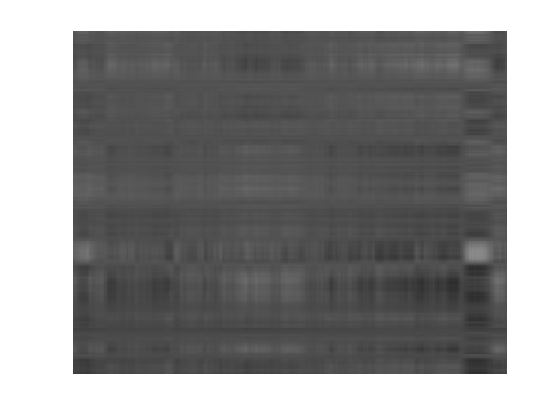

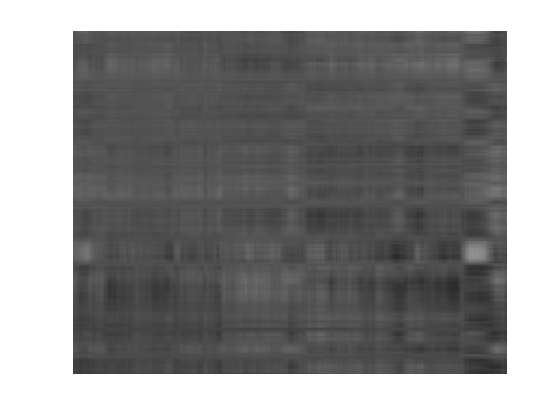

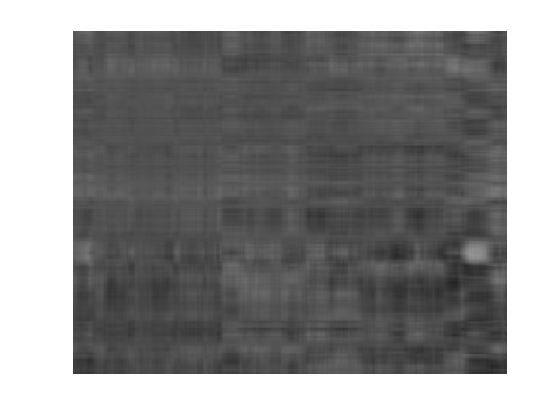

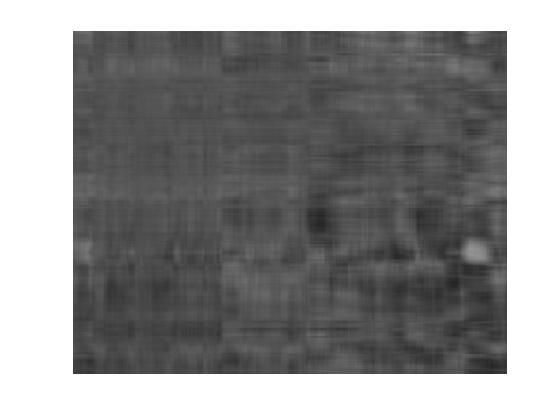

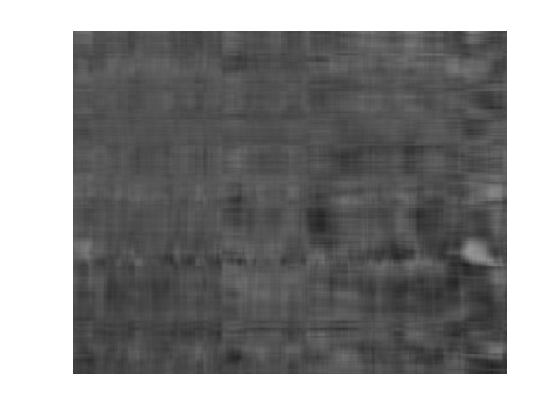

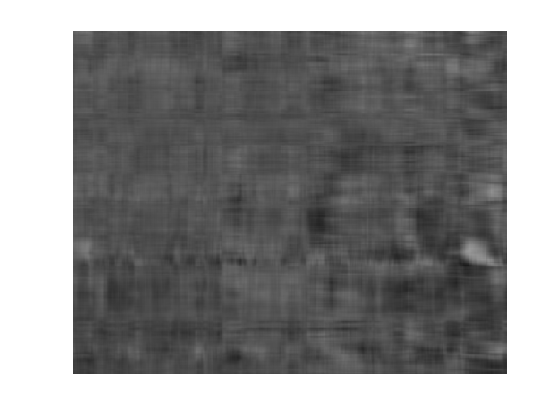

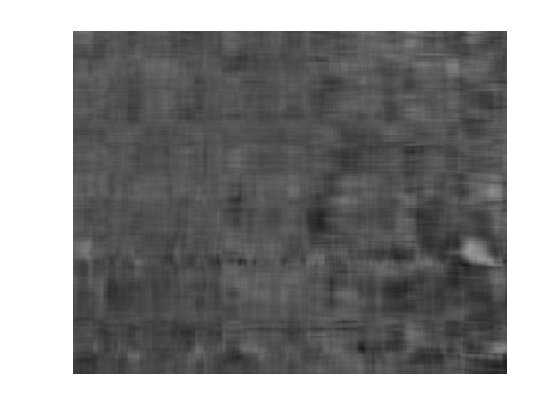

nEigs = 1:20;
for iter=1:size(nEigs,2)
PCs = nEigs(iter);
VV=V(:,1:PCs);
Y=VV'*X; % project data onto PCs
XX=VV*Y; % convert back to original basis
XX=XX+repmat(mn,1,n); % add the row means back on
figure;
image(XX),colormap(map),axis off; % display results
end

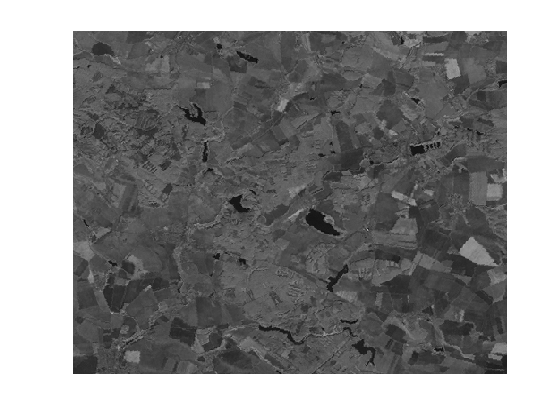

% Show the last component
VV=V(:,1:m);
Y=VV'*X; % project data onto PCs
XX=VV*Y; % convert back to original basis
XX=XX+repmat(mn,1,n); % add the row means back on
figure;
image(XX),colormap(map),axis off; % display results

sum(sum(XX-fly))

ans = 7.9439e-12